clear all;
close all;
clc;

% CA CFAR Parameters
N  = 1024;  % Sample Size
NG = 3;     % Guard Cells
NR = 6;    % Reference Cells
PFA = 10^-6; % Probability of False Alarm

Load RADAR ADC Values

load('data_beauty.mat'); 

% Calculate DFT values 
X = (2/N)*abs(fft(rx_data_adc(:)));

CFAR

% Compute noise estimate in the reference cells
phi_sq = zeros(size(X));
for k = (NR + NG + 1):(N - NR - NG)
    xref = abs(X(k - NR - NG:k - NG - 1)).^2;
    phi_sq(k) = sum(xref) / NR;
end

% Compute required threshold
alpha = NR * (PFA^(-1/NR) - 1);
T = alpha * phi_sq;

% Plot the resulting threshold in the spectra plot
figure(2)
fprintf('%u\n',X);

5.018016e+03
1.087220e+01
1.064175e+01
8.936358e+00
1.538864e+01
1.975713e+01
2.658212e+01
3.760430e+01
1.632232e+01
2.382107e+01
4.931790e+01
6.294298e+01
6.982484e+01
6.463026e+01
1.357042e+02
2.345945e+02
4.276590e+02
6.130903e+02
3.198562e+02
7.960049e+02
4.226531e+02
4.843210e+01
7.575368e+01
2.484399e+01
9.383753e+01
1.347219e+01
4.358681e+01
2.529739e+01
2.546159e+01
2.425326e+01
1.819340e+01
9.128481e+00
8.834870e+00
1.851376e+01
2.356651e+01
2.373006e+01
1.111873e+01
1.323045e+01
2.914705e+01
1.043670e+01
1.599806e+01
1.382761e+01
1.446365e+01
1.188002e+01
1.253701e+01
1.153815e+01
1.044789e+01
1.138522e+01
9.899829e+00
1.059134e+01
1.016415e+01
1.039425e+01
9.954906e+00
9.129411e+00
9.157703e+00
9.306030e+00
8.963266e+00
8.660078e+00
8.077629e+00
8.496576e+00
7.896603e+00
8.098417e+00
7.773143e+00
7.778454e+00
7.515369e+00
7.652483e+00
7.179628e+00
7.255274e+00
7.138441e+00
6.993094e+00
6.927160e+00
6.842387e+00
6.741961e+00
6.714664e+00
6.492224e+00
6.441062e+00
6.154953e+00

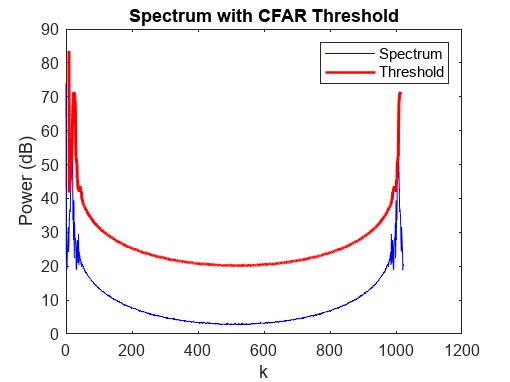

plot(0:N-1, 20*log10(X), 'b'); % Plot the spectrum
hold on
plot(0:N-1, 10*log10(T), 'r', 'LineWidth', 1.5); % Plot the threshold
xlabel 'k'
ylabel 'Power (dB)'
title('Spectrum with CFAR Threshold');
legend('Spectrum', 'Threshold')

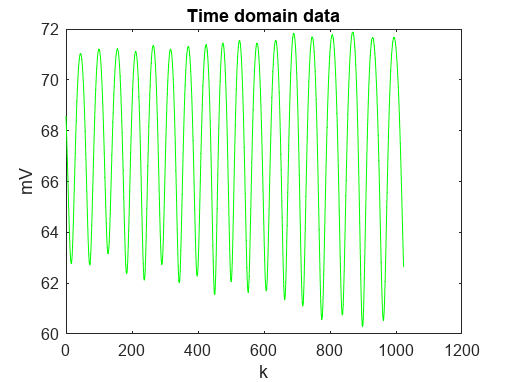


figure(3)
plot(0:N-1,20*log10(rx_data_adc(:)), 'g');
xlabel 'k'
ylabel 'mV'
title('Time domain data');


% Count the number of targets (exceeding the threshold)
numTargets = sum(abs(X) > T);

disp(['Number of Targets: ' num2str(numTargets)]);

Number of Targets: 18
